# AutoFFT v1.3.0 - User Manual

Luboš Smolík

University of West Bohemia

contact: carlist@ntis.zcu.cz

## License Information

This code is published under BSD-3-Clause License.

Copyright (c) 2017-2021

Lubos Smolik, University of West Bohemia

e-mail: carlist@ntis.zcu.cz

## Introduction

Signal Processing Toolbox™ provides several functions to power spectrum estimation, including `pspectrum` and `stft`. Although these functions are excellent and well-documented, they might be cumbersome in some engineering applications. These applications include estimating magnitudes of vibration, noise and other discrete-time signals in engineering units or comparing theoretical results with measurements.

In such applications, you can use `autofft`, a Matlab function to estimate the discrete Fourier transform (DFT), which mimics options of the Brüel & Kjaer FFT analysers. Based on your input, autoFFT segments signal, applies window functions and spectral averaging. The resulting DFT can be returned in various engineering spectral units, including magnitude, RMS, peak-to-peak and power spectral density (PSD). `autofft` can also estimate spectral derivation or spectral integral of DFT and even perform the short-time Fourier transform (STFT).

### When to use `autofft`

- You want to estimate magnitudes of components in your data in engineering units, e.g. m/s, V or Pa.

- You want to have better control over the setup of the frequency analyser than is possible with pspectrum.

- You want to use spectral derivation or spectral integration of DFT. 

### What's new in v1.3?

- A brand new user manual is a part of this release.

- Syntax change: `[s, f, t, setup] = autofft(___)` returns the times `t` at which the STFT is evaluated.

- Syntax change: The setup of the FFT analyser is now specified using `setup` structure; parameters used in the `setup` structure have the same names as parameters used in `pspectrum` and `stft` functions. Output variable `setup `can also be used as input. The structure `fftset` used in the previous versions can still be used to specify the analyser setup. However, `fftset` is no longer documented.

- New functionality: Overlap length can be now set in samples using the `'OverlapLength'` parameter. 

- Bug fix: `'OverlapPercentage'` 100% or higher is now automatically decreased to a realistic value.

- Bug fix: All windows are now treated as column vectors. Row vectors could cause an error during the application of a window to data.

### Compatibility and requirements

- Created with R2021a

- Compatible with R2013a to R2021a

- Requires [Signal Processing Toolbox](https://www.mathworks.com/products/signal.html?s_tid=FX_PR_info)

## Syntax

## Description

`s = autofft(xs, fs)` returns the DFT or STFT `s` of `xs` using sampling frequency `fs` (Hz). `xs` can be either a vector or an array consisting of column vectors.

`s = autofft(xs, ts)` returns the DFT or STFT `s` of `xs` using a vector of time stamps `ts` (s). Also returns the frequencies `f` at which the DFT or STFT `s` is evaluated. 

`[___] = autofft(___, setup)` performs the DFT or STFT name-value pair arguments specified in structure `setup`.

`[s, f] = autofft(___)` returns the frequencies `f` at which the DFT or STFT `s` is evaluated.

`[s, f, setup] = autofft(___)` returns the setup of the FFT analyser.

`[s, f, t, setup] = autofft(___)` returns the times `t` at which the STFT is evaluated.

## Examples

### Perform DFT of a single signal

Generate a testing voltage signal with a duration of 1 second with harmonic components at 80 Hz and 150 Hz.

dt = 1e-3;                                      % Sampling period (s)
T  = 1;                                         % Signal duration (s)
t  = dt:dt:T;                                   % Time vector 
S  = sin(2*pi*50*t) + 0.5 * sin(2*pi*150*t);    % Voltage (V)

Corrupt the signal with zero-mean white noise with a variance of 4.

X = S + 2*randn(size(t));

Estimate the auto spectrum of the noisy signal.

[s, f] = autofft(X, t);

Plot the result. The magnitudes are roughly squares of the effective values (RMS). The discrepancies are present due to the added noise. The effect of the noise can be reduced by spectral averaging, which is in section Spectral Averaging.

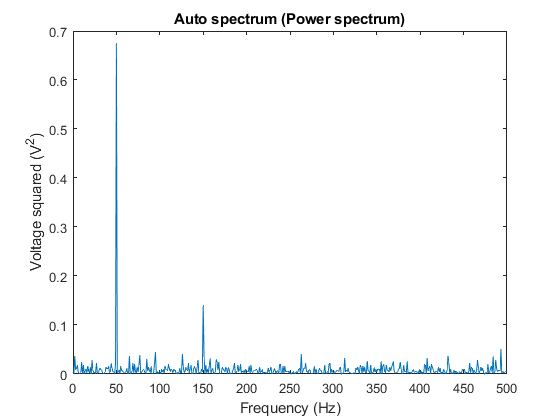

figure;
plot(f, s);
xlabel("Frequency (Hz)")
ylabel("Voltage squared (V^2)")
title("Auto spectrum (Power spectrum)")

### Modify the analyser setup

Using vector `X` from the previous example, one can check a setup used by the FFT analyser using the following code:

[s, f, setup] = autofft(X, t);

Now, the setup can be displayed.

disp(setup)

       SamplingFrequency: 1000
            DataDuration: 1
              DataLength: 1000
               FFTLength: 1000
          TimeResolution: 1
     FrequencyResolution: 1
       HighPassFrequency: NaN
        LowPassFrequency: 500
                  Window: "uniform"
    WindowNoiseBandwidth: 1
           OverlapLength: 500
       OverlapPercentage: 50
               Averaging: "linear"
        NumberOfAverages: 1
            SpectralUnit: "power"
             jwWeigthing: "none"



Change the `'SpectralUnit'` parameter to `'rms'`  and use the modified setup in the FFT analyser.

setup.SpectralUnit = "rms";
[sLin, f, setup] = autofft(X, t, setup);
disp(setup)

       SamplingFrequency: 1000
            DataDuration: 1
              DataLength: 1000
               FFTLength: 1000
          TimeResolution: 1
     FrequencyResolution: 1
       HighPassFrequency: NaN
        LowPassFrequency: 500
                  Window: "uniform"
    WindowNoiseBandwidth: 1
           OverlapLength: 500
       OverlapPercentage: 50
               Averaging: "linear"
        NumberOfAverages: 1
            SpectralUnit: "RMS"
             jwWeigthing: "none"



Plot the results.

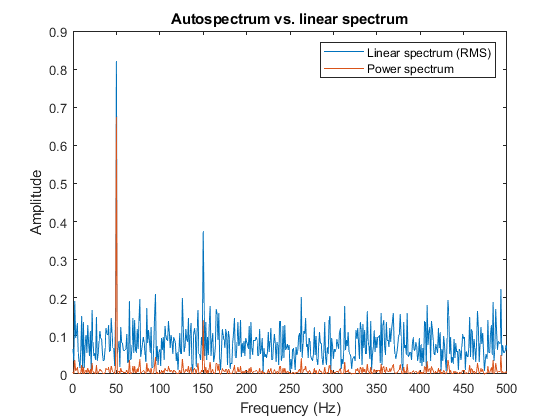

figure;
plot(f, [sLin, s]);
xlabel("Frequency (Hz)")
ylabel("Amplitude")
title("Autospectrum vs. linear spectrum")
legend("Linear spectrum (RMS)", "Power spectrum")

The structure containing the analyser setup can also be constructed manually, field by field. In such a case, field names and their values are case insensitive, and unspecified parameters are generated internally.

userSetup = struct("spectralunit", "rms");

Use `userSetup` in the FFT analyser and compare the resulting spectrum with the previously computed spectrum stored in variable `sLin`.

sLin2 = autofft(X, t, userSetup);
maxError = max(abs(sLin - sLin2));
disp("Maximum difference between sLin and sLin2 is " + maxError)

Maximum difference between sLin and sLin2 is 0


### Perform DFT of multiple signals

Generate three testing voltage signals with a duration of 2 seconds with various harmonic components.

dt = 1e-3;                                          % Sampling period (s)
fs = 1/dt;                                          % Sampling frequency (Hz)
T  = 2;                                             % Signal duration (s)
t  = dt:dt:T;                                       % Time vector 
S1 = sin(2*pi*50*t) + 0.5 * sin(2*pi*150*t);        % Signal 1 (V)
S2 = 0.7 * sin(2*pi*80*t) + 0.5 * sin(2*pi*100*t);  % Signal 2 (V)
S3 = 0.8 * sin(2*pi*90*t) + 0.9 * sin(2*pi*120*t);  % Signal 3 (V)

Arrange the testing signals into an array and corrupt the signals with zero-mean white noise with a variance of 1. Note that the testing signals have to be converted to **column vectors**.

X = [S1(:), S2(:), S3(:)];
X = X + randn(size(X));

Construct the structure containing the analyser setup and divide the testing signals into 1 s long segments using `'TimeResolution'` parameter. The segments are overlapping by 75 % and the Hann window is applied. The magnitude of the resulting spectra is equal to a zero-to-peak value.

setup = struct("TimeResolution", 1, "Window", "hann", "OverlapPercentage", 75, "SpectralUnit", "peak");

Perform DFT of the testing signals and plot results.

[s, f] = autofft(X, t, setup);
disp(setup)

       TimeResolution: 1
               Window: "hann"
    OverlapPercentage: 75
         SpectralUnit: "peak"



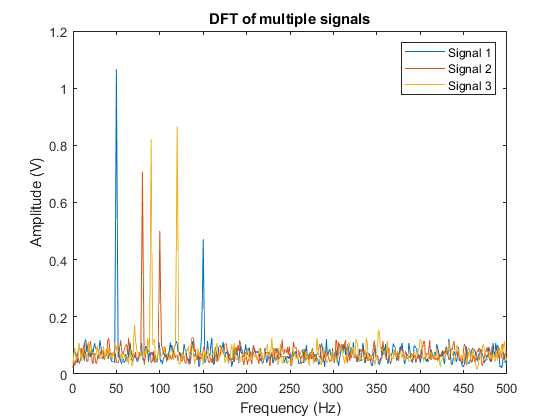


plot(f, s);
xlabel("Frequency (Hz)")
ylabel("Amplitude (V)")
title("DFT of multiple signals")
legend("Signal 1", "Signal 2", "Signal 3")

### Perform STFT of a single signal

Generate two seconds of a voltage controlled oscillator output, controlled by a sinusoid sampled at 10 kHz.

fs = 10e3;                              % Sampling frequency (Hz)
t  = 0:1/fs:2;                          % Time stamps (s)
x  = vco(sin(2*pi*t),[0.1 0.4]*fs,fs);  % Oscillator output (V)

Compute and plot the STFT of the signal. Use a Kaiser window of length 256 and shape parameter $\beta =5$. Specify the length of overlap as 220 samples and the frequency resolution as 40 Hz. The spectral unit of the STFT is set to zero-to-peak. Note that in contrast to the `stft` function, additional parameter `'Averaging'` has to be set to `'none'`. This parameter switches between the DFT and STFT.

setup = struct("FrequencyResolution", 40, "Window", kaiser(256,5), "OverlapLength", 220, "SpectralUnit", "peak", "Averaging", "none");
[s, f, t, setup] = autofft(x, fs, setup);

Note that if the window length does not correspond with the FFT length, autofft uses an interpolated window function. Now, plot the STFT with default colormap and view.

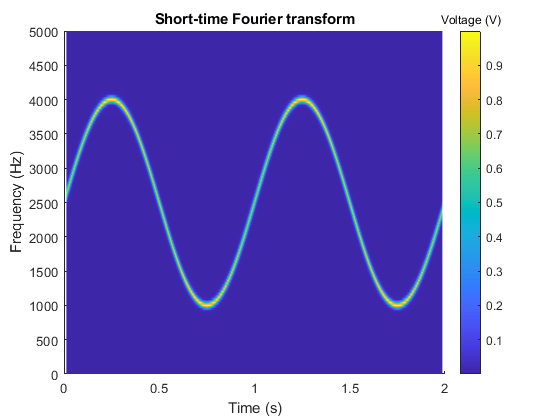

figure;
surface(t, f, s);
shading interp;
xlabel("Time (s)")
ylabel("Frequency (Hz)")
title("Short-time Fourier transform")
c = colorbar;
title(c, "Voltage (V)")

### Perform STFT of multiple signals

Generate a quadratic chirps of length 2 s sampled at 1 kHz:

t  = 0:0.001:2;               % 2 secs @ 1kHz sample rate
yq = chirp(t,100,1,200,'q');  % Start @ 100Hz, cross 200Hz at t=1sec

Corrupt the chirp with zero-mean white noise and arrange  both original and corrupted chirps into a single array. Note that the testing signals have to be converted to **column vectors**.

yqCor = yq + randn(size(yq));
ych = [yq(:), yqCor(:)];

Compute and plot the STFT of both chirps. Set the frequency resolution to 10 Hz and use a Blackmann-Harris window with overlap 90 %.

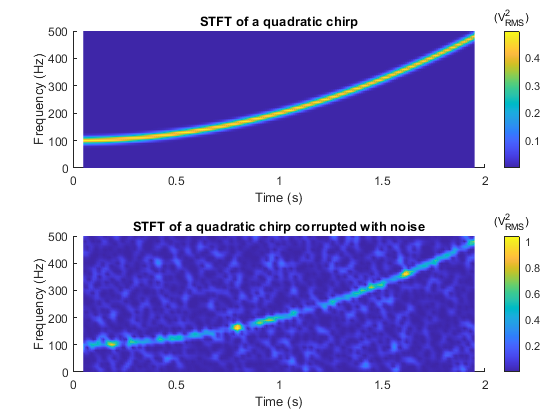

setup = struct("FrequencyResolution", 10, "Window", "b", "OverlapPercentage", 90, "Averaging", "none");
[s, f, t, setup] = autofft(ych, t, setup);

tiledlayout(2, 1);
nexttile;
surface(t, f, squeeze(s(:,:,1)));
ylim([0 f(end)]);
shading interp;
xlabel("Time (s)")
ylabel("Frequency (Hz)")
title("STFT of a quadratic chirp")
c = colorbar;
title(c, "(V_{RMS}^2)")

nexttile;
surface(t, f, squeeze(s(:,:,2)));
ylim([0 f(end)]);
shading interp;
xlabel("Time (s)")
ylabel("Frequency (Hz)")
title("STFT of a quadratic chirp corrupted with noise")
c = colorbar;
title(c, "(V_{RMS}^2)")

## Detailed Description of the Analyser Setup

### Frequency resolution

The frequency resolution $\Delta f$ is the difference in frequency between two consecutive spectral lines (bins) of the DFT. Two signal components are indistinguishable if their frequencies $f_1$ and $f_2$ are close relatively to the frequency resolution. By rule of thumb, two independent components should be separated at least by one spectral line if the uniform window is used, i.e. $\left|f_1 -f_2 \right|\ge 2\cdot \;\Delta f$.

The frequency resolution is equal to


$$\Delta f=\frac{f_s }{N_s }=\frac{1}{T}$$


where $f_s$ is sampling frequency in Hz, $N_s$ is a total number of samples in the analysed signal and $T$ is a length of the analysed signal in s. **By default**, the analysed **signal is treated as one segment** and the frequency resolution of the DFT depends on the total number of samples $N_s$. The freqeuncy resolution can be adjusted in order to perform the STFT or employ the spectral averaging using one of the following parameters:

`'FFTLength'`** — Number of DFT points**

`total number of samples (default) | positive integer`

If `'FFTLength'` $n_s$ is provided, then the analysed signal is divided into segments with each containing $n_s$ samples.

**Data type:**` double | single`

`'TimeResolution'`** —  Length (in seconds) of the DFT**

`duration of the signal (default) | positive scalar`

If `'TimeResolution'` $T_s$ is provided, then  the analysed signal is divided into segments with each containing $T_s \cdot f_s$ samples.

**Data type:**` double | single`

`'FrequencyResolution'`** — Desired frequency resolution of the DFT**

`fs / size(xs, 2) (default) | positive scalar`

If `'FrequencyResolution'` $\Delta f$ is provided, then the analysed signal is divided into segments with each containing $f_s /\Delta f$ samples.

**Data type:**` double | single`

If the user-specified number of samples per segment is higher than actual length of the analysed signal , the value of $n_s$ is internally set to $n_s =N_s$. Overlapping of adjoining segments is explained hereafter.

**Note:** If `'FFTLength'` is set, then both `'TimeResolution'` and `'FrequencyResolution'` are ignored by the analyser. If `'TimeResolution'` is set, then `'FrequencyResolution'` is ignored by the analyser. This behaviour is different from the `stft` function, where `'FFTLength'` and `'TimeResolution'` can be adjusted independently.

### High-pass filtering

`'HighPassFrequency'`** — Cut-off frequency of the high-pass filter**

`NaN (default) | real number`

- If `fc` `is` `NaN `or `'HighPassFrequency'` is not provided, no high-pass filter is applied.

- If `fc = 0`, only the direct (DC) component is removed with the use of the `detrend` function.

- If `fc > 0`, the `detrend` function is applied and the high-pass filter with the cut-off frequency `fc` is applied subsequently.

- If `fc < 0`, then only the high-pass filter with the cut-off frequency `abs(fc)`

The high-pass filter is often selected if the analysed signal is contaminated with low-frequency data or a constant offset (DC), which is not in the interest frequency range. `autofft` has built-in digital high-pass filters, which correspond to high-pass filters used in **Brüel & Kjaer** **IDAe** **modules.** These high-pass filters are the 1st order elliptic filters with the slope -20 dB/dec. Attenuation at the cut-off frequency is -0.1 dB. A typical magnitude response is shown in the figure below.

**Data type:**` double | single`

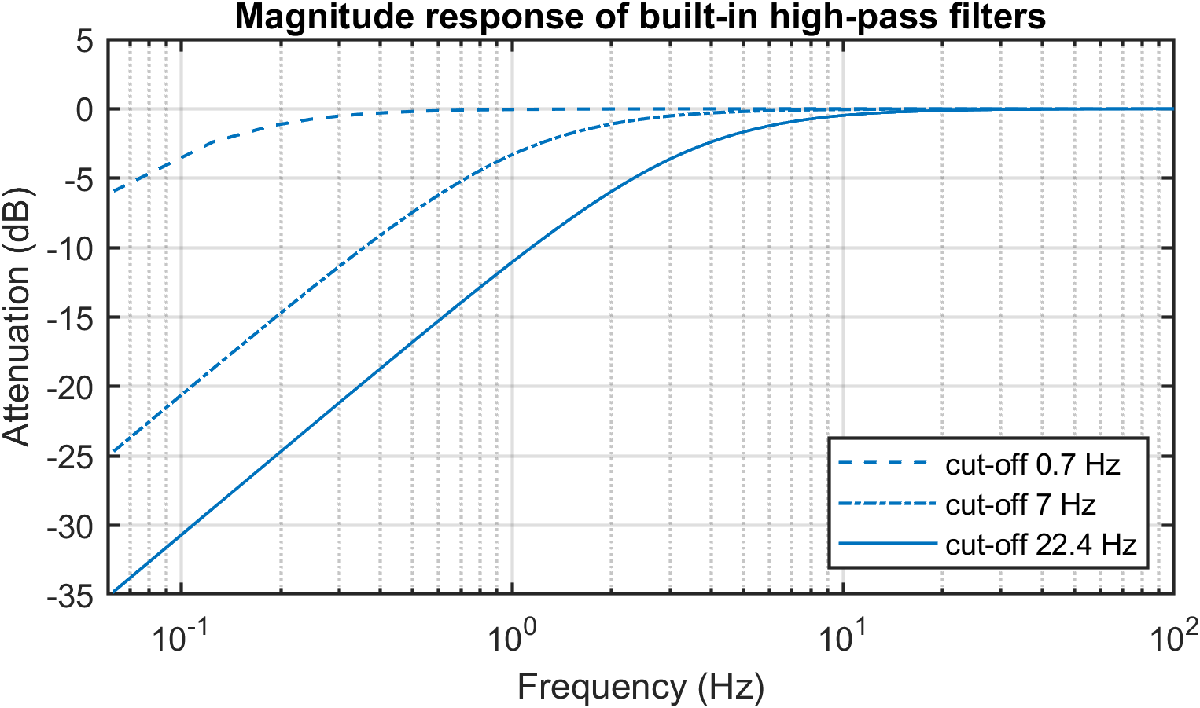

### Low-pass filtering

`'LowPassFrequency'`** — Maximum frequency of interest**

`half of the sampling frequency (default) | positive scalar up to half of the sampling frequency`

In the current version of `autofft`, `'LowPassFrequency'` is used to specify the maximum frequency of interest. Data at higher frequencies are not used for the spectral averaging and evaluation of spectral units and are not returned in output variables. No low-pass filter is applied in the time domain. Therefore, you can use this parameter to limit the output frequency range and slightly speed up computations. **Recommended** maximum value of `'LowPassFrequency'` is $f_{s\;} /2\ldotp 56$, where $f_{s\;}$ is the sampling frequency.

**Data type:**` double | single`

### Applying a window function

`'Window'`** — Applied window function / time weighting**

`'uniform' (default) | 'blackmann' | 'flat-top' | 'hann' | 'hamming' | 'kaiser' | 'kaiserA.B' | vector`

When you apply a window function, each segment of the analysed signal is multiplied by this window function. This process is sometimes called *time weighting*. The purpose of time weighting is to reduce unwanted effects as *spectral leakage* and *passband ripple* or to improve the signal-to-noise ratio. The following window functions can be choosen: 

- `'u'` or `'uniform'` applies the uniform window, also known as the *rectangular window*, *flat window* or *box-car window*. The application of the uniform window is not really time weighting because this window leaves the analysed signal as is. This window 

- `'b'` or `'blackmann'` applies 

- `'f'` or `'flat-top'` applies 

- `'h'` or `'hann'` applies the Hann window.

- `'m'` or `'hamming'` applies

- `'k'` or `'kaiser'` applies

- `'kA.B'` or `'kaiserA.B'` applies

- Alternatively, the window function can be specified as a vector. In this case, the length of the vector should be the same as `'FFTLength'`. Otherwise, `autofft` interpolates the vector to match `'FFTLength'` employing the modified Akima algorithm. This behaviour is different from the `stft` function, where `'FFTLength'` and `'Window'` length can be adjusted independently.

Leakage

Passband ripple, or picket-fence effect, occurs when a peak in the spectrum of the analysed signal does not coincide with the frequency of calculated spectral lines

Each window function has certain characteristics, including:

- **Noise bandwidth**

- **Ripple **characterises the uncertainty with which the magnitude of the analysed signal is estimated. 

- **highest side lobe **

- **side lobe fall-off rate**

**Data type:**` char | string | double | single`

### Overlapping

### Spectral averaging

`'Averaging'`** — Algorithm for spectral averaging**

`'linear' (default) | 'energy' | 'max' | 'median' | 'min' | 'var' | 'none'`

**Data type:**` char | string`

### Spectral differentiation and integration -$j\omega \;$weighting

`'jwWeigthing'`** — Frequency-domain post-weighting**

`'1' (default) | '1/jw2' | '1/jw' | 'jw' | 'jw2'`

**Data type:**` char | string`

### Spectral units

`'SpectralUnit'`** — Engineering unit of the output spectra**

`'pow' (default) | 'rms' | 'pk' | 'pp' | 'psd' | 'rsd'`

Various types of the analysed signals require different spectral units. `autofft` works internally with complex spectra, however, the spectral averaging is performed emploing the spectral units. The available spectral units include:

- `'pow'` or `'power'` is a useful unit for analysing stationary deterministic signals 

- `'rms'` estimates  

- `'pk'` or `'0-pk'` applies 

- `'pp'` or `'pk-pk'` applies the Hann window.

- `'psd'` or `'asd'` estimates *power spectral density* of the analysed signal. The power spectral density is a correct unit for displaying broad-band random signals.

- `'rsd'` or `'rmssd'` is equal to the square root of the power spectral density. This spectral unit allows 

**Data type:**` char | string`

## References

- RANDALL, R. B. *Frequency Analysis*. 3rd edition. Naerum (Denmark): Brüel & Kjaer, 1987.

- *PULSE LabShop* [software]. v21.0.0. Naerum (Denmark): Brüel & Kjaer, 2016.

- *LabView *[software]. v2019. Austin (USA): National Instruments, 2019.

- *Simcenter Testlab* [software]. v2019.1. Munich (Germany): Siemens, 2019.

## Appendix A: Road Map

Features which I plan to implement in future releases of `autofft` (in no specific order):

- support for tables and timetables,

- new spectral units (Fourier spectrum, energy spectral density)

- new analysis modes (full-spectrum, frequency zoom, envelope analysis, Bode plot),

- advanced multi-buffering and triggering,

- acoustic weighting, and

- GUI (?)

## Appendix B: Historical Release Notes

**v1.3.0**

- A brand new user manual is a part of this release.

- Syntax change: `[s, f, t, setup] = autofft(___)` returns the times `t` at which the STFT is evaluated.

- Syntax change: The setup of the FFT analyser is now specified using `setup` structure; parameters used in the `setup` structure have the same names as parameters used in `pspectrum` and `stft` functions. Output variable `setup `can also be used as input. The structure `fftset` used in the previous versions can still be used to specify the analyser setup. However, `fftset` is no longer documented.

- New functionality: Overlap length can be now set in samples using the `'OverlapLength'` parameter. 

- Bug fix: `'OverlapPercentage'` 100% or higher is now automatically decreased to a realistic value.

- Bug fix: All windows are now treated as column vectors. Row vectors could cause an error during the application of a window to data.

**v1.2.5a (hotfix)**

- Bug fix: Outputs which appeared twice in `setup` now appear only once.

**v1.2.5**

- New functionality: An optional highpass filtering has been implemented.

**v1.2.4b (hotfix)**

- Bug fix: Overlap length (in samples) returned in setup is now correct.

**v1.2.4a**

- Bug fix: Error occuring during the estimation of auto spectrum has been fixed.

**v1.2.4** 

- Documentation has been improved.

- Syntax change: Results of the STFT of multiple signals are now returned as 3D array rather than cell array of 2D arrays.

- New functionality: New types of averaging:* median filter *and *variance of spectral unit*.

- Performance has been improved significantly.

- Accuracy of PSD and RMSSD estimates has been slightly improved.

- Dealing with a content at the Nyquist frequency has been improved.

**v1.2.3 **

- Syntax change: The analyser setup can be returned as an output variable.

- New functionality: User can define frequency resolution of the analyser using `'df'` parameter.

- New functionality: The window function can be directly specified as a vector.

- Warning messages are now displayed if user specified paramters are changed internally.

**v1.2.2a (hotfix)**

- Bug fix: Error occuring during peak hold averaging has been fixed.

**v1.2.2** 

- New functionality: The Kaiser-Bessel window parameter (beta) can now be specified.

- Autospectrum is now properly square of RMS rather than square of 0-Pk.

- Relations for evaluation of PSD and RMSPSD now consider the noise power bandwidth of the used window function. 

**v1.2.1**

- Syntax change: Options for `'unit'` and `'peak`' have been merged (into `'unit'`).

- New functionality: Maximum frequency can now be specified using `'lowpass'` parameter.

- New functionality: New types of averaging have been added: *no averaging*, *energy averaging* and *minimum value hold*.

- Relations for evaluation of PSD and RMSPSD have been improved.

- Dealing with a content at the Nyquist frequency has been improved.

**v1.2.0** 

- Syntax change: Input parameters are now specified in a structured variable. Due to this change, v1.2.0 is not compatible with the previous releases.

**v1.1.2**

- Syntax change: Input parameter `xs` can now be an array.

**v1.1.1**

- Performance has been improved.

- Handling of input vectors with the even number of samples has been improved.

**v1.1.0**

- Relations for evaluation of spectral units now consider the influence of non-uniform windows.

- Parameters `'nwin'` and `'overlap'` can now be skipped by user.